# Ex 1 - Consensus [part 3]

clear variables
close all
clc
rng(1)

## Rng seed

rng(1)

## Global parameters

N = 25;                         % number of nodes
sim_len = 200;                  % simulations length

% initial state
v = rand(N,1);                  % observations
v_avg = mean(v);                % value of average consensus

## Complete graph

A = ones(N) - diag(ones(N, 1));
d = sum(A,1);                   % degree vector
D = diag(d);                    % degree matrix
L = D - A;                      % laplacian matrix

#### Average Consensus

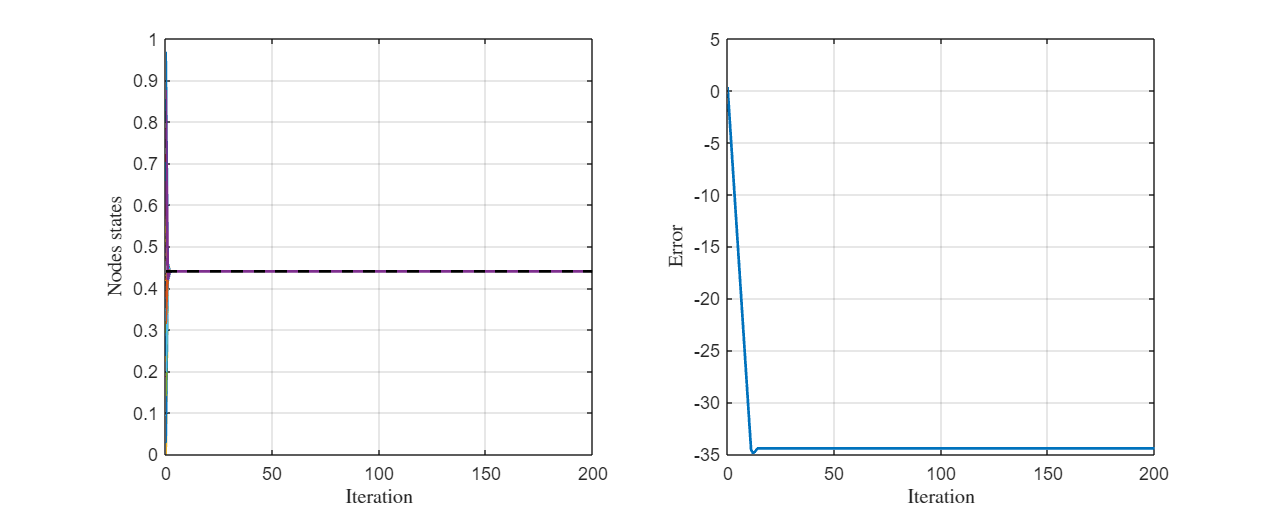

eps = 1/max(diag(L));           % choose epsilon
P = eye(N) - eps*L;             % design consensus matrix

X = [v, zeros(N,sim_len)];      % trajectories of nodes states

for k = 1:sim_len
    X(:,k+1) = P*X(:,k);        % update nodes' states
end
% plot result
plot_results(X,v_avg)

#### Robust Ratio consensus

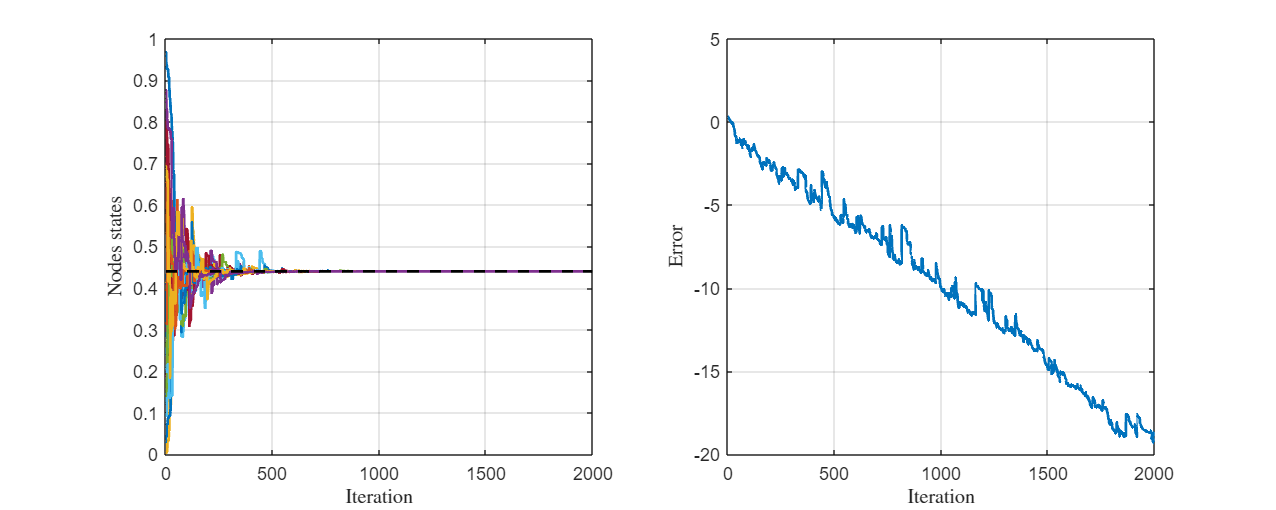

% packet loss probability
pl = 0.6;

% nodes states and auxiliary states
X = [v, zeros(N,4*sim_len)];
Y = [v, zeros(N,4*sim_len)];
S = [ones(N,1), zeros(N,4*sim_len)];

% counters of mass sent
S_y = zeros(N,1);
S_s = zeros(N,1);

% counters of mass received
R_y = zeros(N);
R_s = zeros(N);

for k = 1:10*sim_len
    
    % propagate old states
    X(:,k+1) = X(:,k);
    Y(:,k+1) = Y(:,k);
    S(:,k+1) = S(:,k);
    
    % choose broadcaster node
    i = randi(N);

    % update the auxiliary states
    Y(i,k+1) = Y(i,k)/(d(i)+1);
    S(i,k+1) = S(i,k)/(d(i)+1);
    
    % update the counters
    S_y(i) = S_y(i) + Y(i,k+1);
    S_s(i) = S_s(i) + S(i,k+1);
    
    % update neighbors' states
    for j = find(A(i,:))
        
        if pl < rand % packet is not lost
            
            % update auxiliary states
            Y(j,k+1) = S_y(i) - R_y(j,i) + Y(j,k);
            S(j,k+1) = S_s(i) - R_s(j,i) + S(j,k);
            
            % update the state
            X(j,k+1) = Y(j,k+1)/S(j,k+1);
            
            % store the counters
            R_y(j,i) = S_y(i);
            R_s(j,i) = S_s(i);
            
        end
    end    
end

% plot result
plot_results(X,v_avg)

## Circle graph

A = zeros(N);
for ii = 1:N
    for jj = 1:N
        if ii == jj+1 || ii+1 == jj
            A(ii, jj) = 1;
        end
    end
end
A(1,N) = 1;
A(N,1) = 1;

d = sum(A,1);                   % degree vector
D = diag(d);                    % degree matrix
L = D - A;                      % laplacian matrix

#### Average Consensus

eps = 1/max(diag(L));           % choose epsilon
P = eye(N) - eps*L;             % design consensus matrix

X = [v, zeros(N,sim_len)];      % trajectories of nodes states

for k = 1:sim_len
    X(:,k+1) = P*X(:,k);        % update nodes' states
end
disp(eig(P))

   -0.9921
   -0.9921
   -0.9298
   -0.9298
   -0.8090
   -0.8090
   -0.6374
   -0.6374
   -0.4258
   -0.4258
   -0.1874
   -0.1874
    0.0628
    0.0628
    0.3090
    0.3090
    0.5358
    0.5358
    0.7290
    0.7290
    0.8763
    0.8763
    0.9686
    0.9686
    1.0000



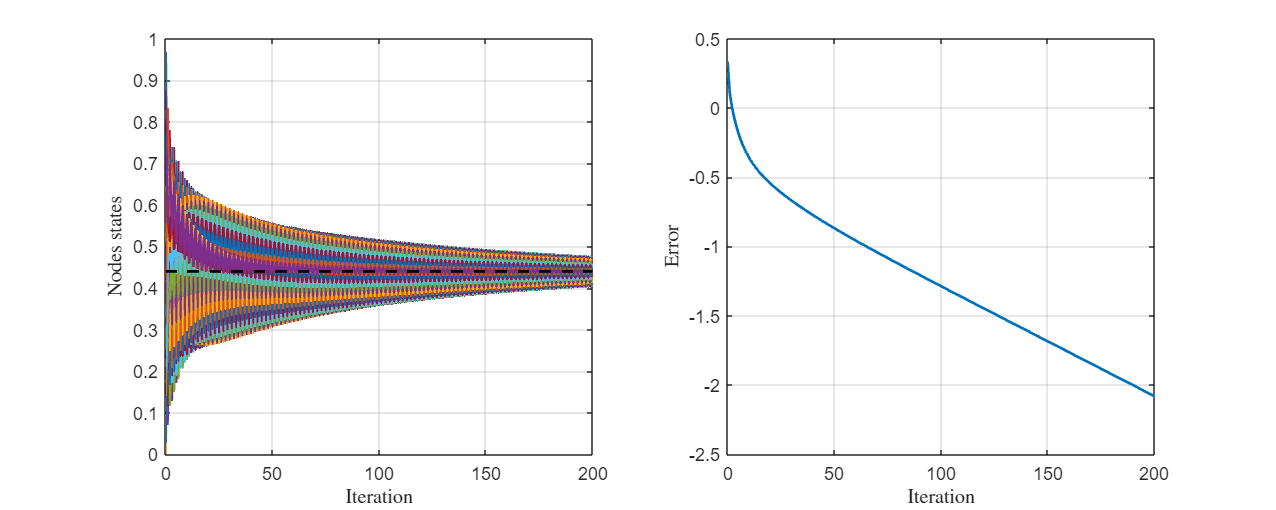

% plot result
plot_results(X,v_avg)

#### Robust Ratio consensus

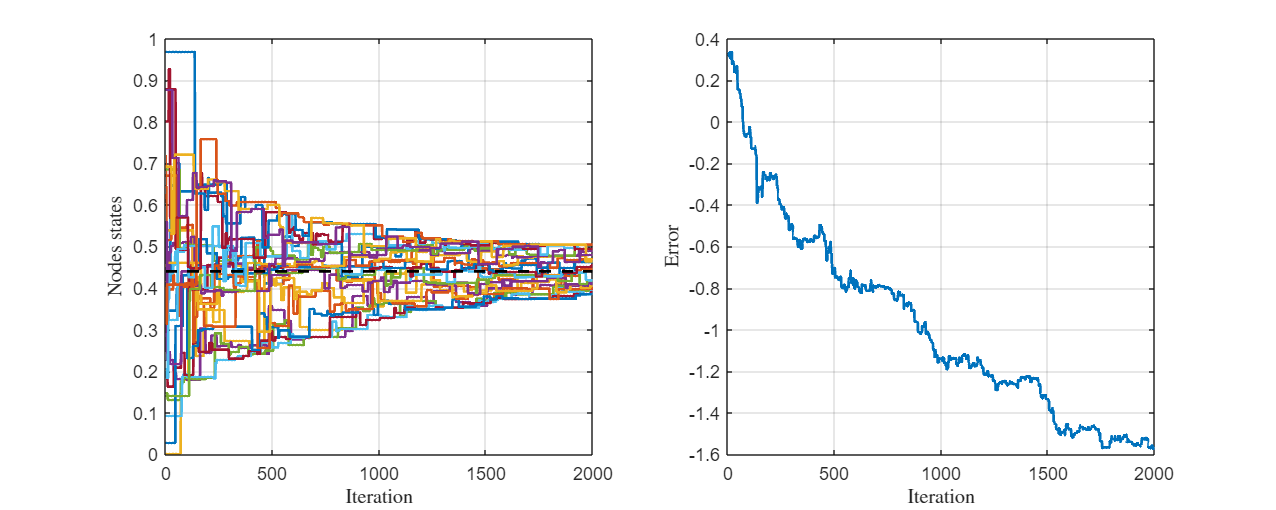

% packet loss probability
pl = 0.6;

% nodes states and auxiliary states
X = [v, zeros(N,4*sim_len)];
Y = [v, zeros(N,4*sim_len)];
S = [ones(N,1), zeros(N,4*sim_len)];

% counters of mass sent
S_y = zeros(N,1);
S_s = zeros(N,1);

% counters of mass received
R_y = zeros(N);
R_s = zeros(N);

for k = 1:10*sim_len
    
    % propagate old states
    X(:,k+1) = X(:,k);
    Y(:,k+1) = Y(:,k);
    S(:,k+1) = S(:,k);
    
    % choose broadcaster node
    i = randi(N);

    % update the auxiliary states
    Y(i,k+1) = Y(i,k)/(d(i)+1);
    S(i,k+1) = S(i,k)/(d(i)+1);
    
    % update the counters
    S_y(i) = S_y(i) + Y(i,k+1);
    S_s(i) = S_s(i) + S(i,k+1);
    
    % update neighbors' states
    for j = find(A(i,:))
        
        if pl < rand % packet is not lost
            
            % update auxiliary states
            Y(j,k+1) = S_y(i) - R_y(j,i) + Y(j,k);
            S(j,k+1) = S_s(i) - R_s(j,i) + S(j,k);
            
            % update the state
            X(j,k+1) = Y(j,k+1)/S(j,k+1);
            
            % store the counters
            R_y(j,i) = S_y(i);
            R_s(j,i) = S_s(i);
            
        end
    end    
end

% plot result
plot_results(X,v_avg)

## Star graph

A = zeros(N);
A(1,2:end) = 1;
A(2:end,1) = 1;

d = sum(A,1);                   % degree vector
D = diag(d);                    % degree matrix
L = D - A;                      % laplacian matrix

#### Average Consensus

eps = 1/max(diag(L));           % choose epsilon
P = eye(N) - eps*L;             % design consensus matrix

X = [v, zeros(N,sim_len)];      % trajectories of nodes states

for k = 1:sim_len
    X(:,k+1) = P*X(:,k);        % update nodes' states
end

disp(eig(P))

   -0.0417
    0.9583
    0.9583
    0.9583
    0.9583
    0.9583
    0.9583
    0.9583
    0.9583
    0.9583
    0.9583
    0.9583
    0.9583
    0.9583
    0.9583
    0.9583
    0.9583
    0.9583
    0.9583
    0.9583
    0.9583
    0.9583
    0.9583
    0.9583
    1.0000



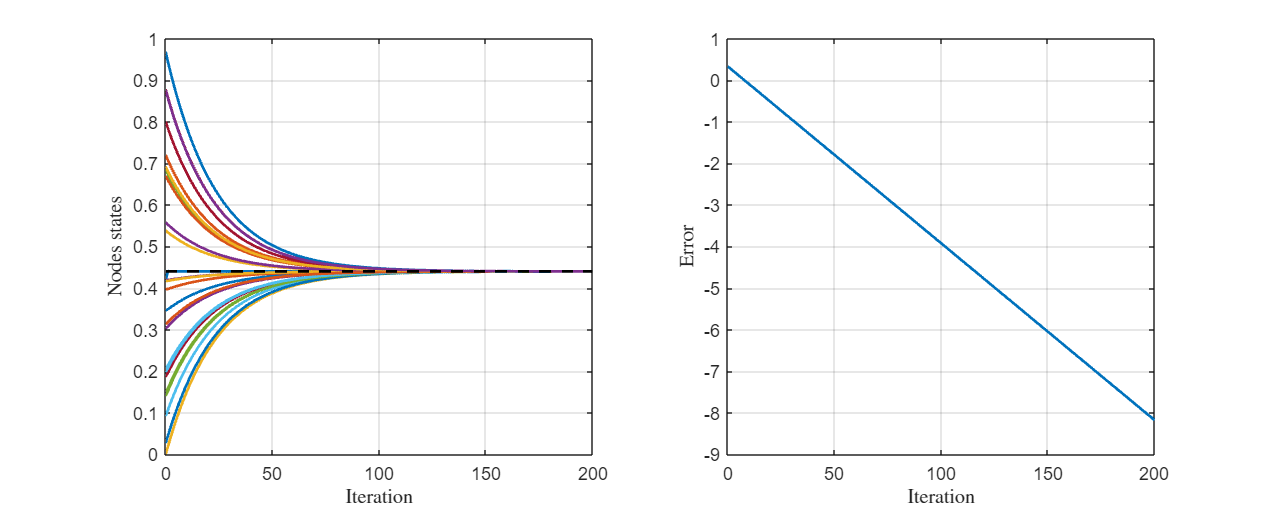


% plot result
plot_results(X,v_avg)

#### Robust Ratio consensus

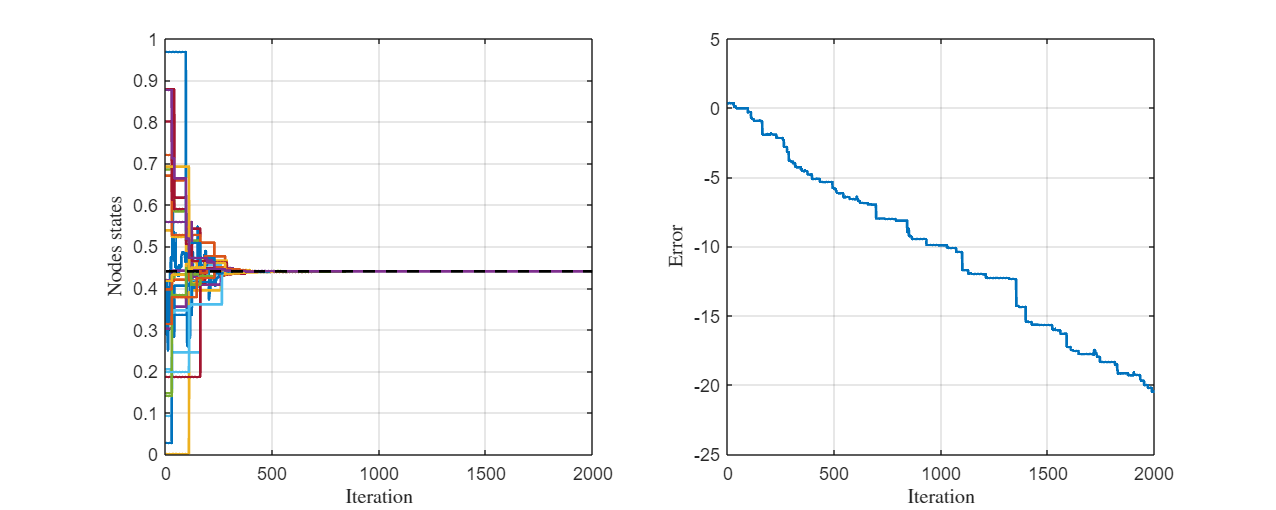

% packet loss probability
pl = 0.6;

% nodes states and auxiliary states
X = [v, zeros(N,4*sim_len)];
Y = [v, zeros(N,4*sim_len)];
S = [ones(N,1), zeros(N,4*sim_len)];

% counters of mass sent
S_y = zeros(N,1);
S_s = zeros(N,1);

% counters of mass received
R_y = zeros(N);
R_s = zeros(N);

for k = 1:10*sim_len
    
    % propagate old states
    X(:,k+1) = X(:,k);
    Y(:,k+1) = Y(:,k);
    S(:,k+1) = S(:,k);
    
    % choose broadcaster node
    i = randi(N);

    % update the auxiliary states
    Y(i,k+1) = Y(i,k)/(d(i)+1);
    S(i,k+1) = S(i,k)/(d(i)+1);
    
    % update the counters
    S_y(i) = S_y(i) + Y(i,k+1);
    S_s(i) = S_s(i) + S(i,k+1);
    
    % update neighbors' states
    for j = find(A(i,:))
        
        if pl < rand % packet is not lost
            
            % update auxiliary states
            Y(j,k+1) = S_y(i) - R_y(j,i) + Y(j,k);
            S(j,k+1) = S_s(i) - R_s(j,i) + S(j,k);
            
            % update the state
            X(j,k+1) = Y(j,k+1)/S(j,k+1);
            
            % store the counters
            R_y(j,i) = S_y(i);
            R_s(j,i) = S_s(i);
            
        end
    end    
end

% plot result
plot_results(X,v_avg)